# HW5

## Exercise 25.6

xyinterval = [-3, 1]

xyinterval =     -3     1


d = 0.235; % m, diameter of the neato
syms f(x,y) r(i) lambda(i) sigma
f(x,y) = (x * y) - x^2 - y^2 - (2 * x) - (2 * y) + 4

$$f(x, y) = -x^{2}+x\,y-2\,x-y^{2}-2\,y+4$$

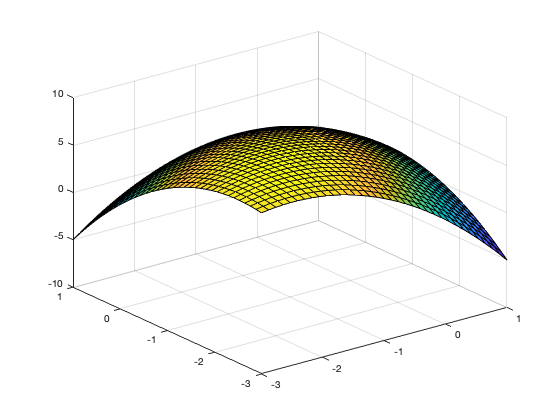

figure(1); clf;
fsurf(f, xyinterval)
zlim([-10, 10])

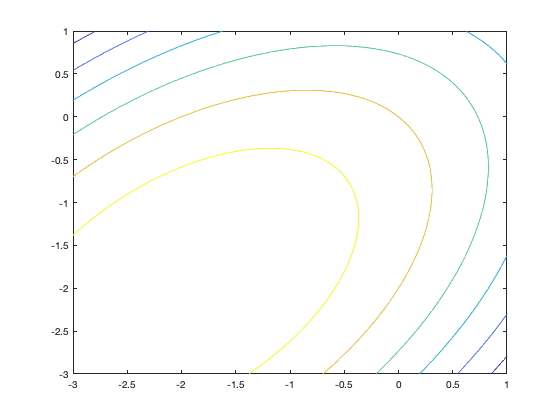

%%% Exercise 25.6.1
figure(2); clf;
fcontour(f, xyinterval)

%%% Exercise 25.6.2 is drawn in OneNote

%%% Exercise 25.6.3
grad = matlabFunction([diff(f, x); diff(f, y)])

grad = function_handle with value:
    @(x,y)[x.*-2.0+y-2.0;x-y.*2.0-2.0]


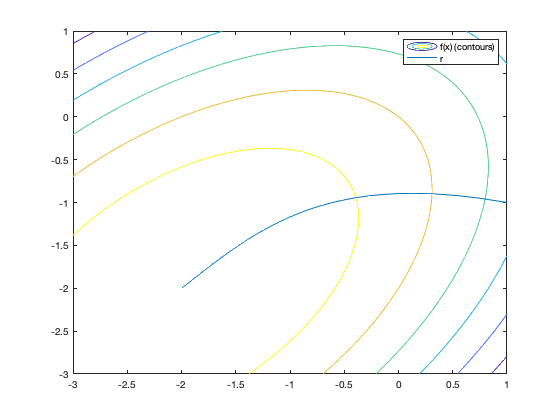


%%% Exercise 25.6.4
r_0 = [1, -1];

grad(r_0(1), r_0(2)); % Gradient at r(0)


%%% Calculate the path

% These values were chosen experimentally
dtdi = 1; % every i is this many seconds
i_max = 200; % We'll calculate this many time steps. It may take fewer to reach the peak.
sigma = 1;
lambda_0 = 0.05; 
rs = zeros(i_max, 2);
lambdas = zeros(i_max, 1);

rs(1, :) = r_0;
lambdas(1) = lambda_0;

for i=2:i_max
    lambdas(i) = lambdas(i - 1) .* sigma;
    gradient = grad(rs(i - 1, 1), rs(i - 1, 2))';
    rs(i, :) = rs(i - 1, :) + (lambdas(i - 1) .* gradient);
end

figure(3); clf;
fcontour(f, xyinterval); hold on; % draw the contours again
plot(rs(:, 1), rs(:, 2)); legend("f(x) (contours)", "r"); hold off;


%%% Exercise 25.6.5

% To figure out the needed turning, we need to calculate the tangent line at i = 0
% I think there's a better, linear algebra way to do this
drs = diff(rs);
dts = ones(size(drs)) * dtdi;
vs = drs ./ dts;
thetas = atan(vs(:, 2) ./ vs(:, 1)) + pi;
theta_0 = pi / 2;

dtheta_0 = thetas(1) - theta_0;

fprintf("If the Neato started at (1, -1) pointing in the +Y direction, you'd need to rotate it %2.2f radians CCW to align with the gradient.", dtheta_0);

If the Neato started at (1, -1) pointing in the +Y direction, you'd need to rotate it 1.37 radians CCW to align with the gradient.

max_speed = 0.1; % m/s, max wheel velocity
max_omega = max_speed * (2 / d) % max rotational speed for given wheel velocity

max_omega = 0.8511

t_to_align = dtheta_0 / max_omega

t_to_align = 1.6137


%%% Exercise 25.6.6
speeds = vecnorm(vs, 2, 2)

speeds =     0.2550
    0.2249
    0.1995
    0.1780
    0.1598
    0.1443
    0.1312
    0.1199
    0.1102
    0.1018
